# SIR simulated data

clearvars; format long
[t,S,I,~,R,beta,xi,Rt] = load_simData();
[S,I,R] = addNoise([0 0.03 0],S,I,R);

Plot the dataset

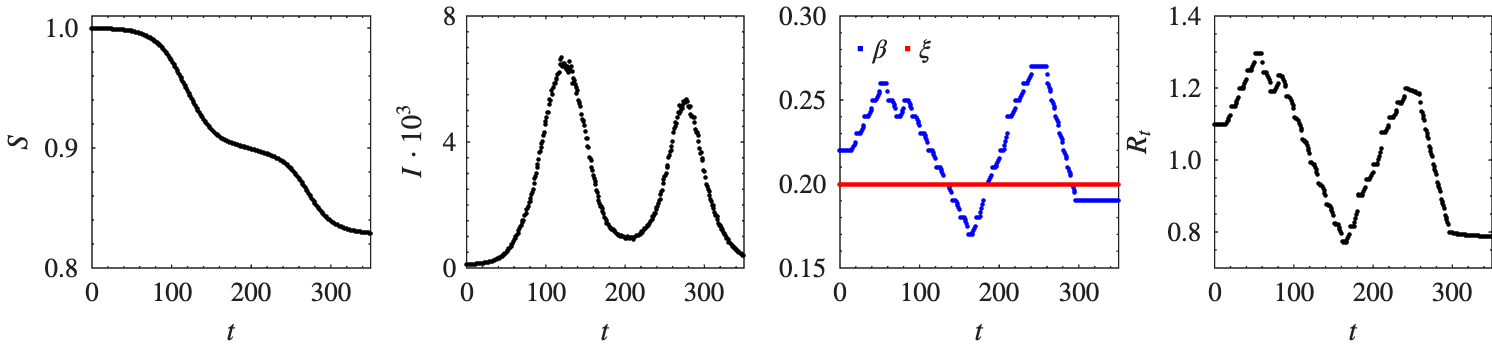

% Colors
colorTeo = [0 0 0];
colorsParam = [0 0 1; 1 0 0];

% Other specs
fontSize = 10; dotSize = 3;

figure; tiledlayout(1,4,"TileSpacing","tight","Padding","tight")
nexttile; hold on
scatter(t,S,'filled','CData',colorTeo,'SizeData',dotSize)
axis([0 350 0.8 1.01]); xticks([0 100 200 300]); yticks([0.8 0.9 1.0]); ytickformat('%.1f')
set(gca,'FontSize',fontSize,'TickLabelInterpreter','latex','XMinorTick','on','YMinorTick','on'); 
xlabel('$t$','Interpreter','latex'); ylabel('$S$','Interpreter','latex'); box on;
nexttile; hold on
scatter(t,I,'filled','CData',colorTeo,'SizeData',dotSize)
axis([0 350 0 0.008]); xticks([0 100 200 300]); yticks([0 4 8].*10^-3); yticklabels({'0','4','8'})
set(gca,'FontSize',fontSize,'TickLabelInterpreter','latex','XMinorTick','on','YMinorTick','on'); box on;
xlabel('$t$','Interpreter','latex'); ylabel('$I\cdot 10^3$','Interpreter','latex'); box on;
nexttile; hold on
plot(0,0,'Color',colorsParam(1,:),'LineWidth',2); plot(0,0,'Color',colorsParam(2,:),'LineWidth',2);
scatter(t,beta.*ones(size(t)),'filled','CData',colorsParam(1,:),'SizeData',dotSize)
scatter(t,xi.*ones(size(t)),'filled','CData',colorsParam(2,:),'SizeData',dotSize)
leg = legend(["$\beta$","$\xi$"],'Interpreter','latex','FontSize',fontSize,'Box','off','Orientation','horizontal',...
    'Position',[0.535 0.76 0.2 0.2]);
leg.ItemTokenSize = [2 2];
axis([0 350 0.15 0.30]); xticks([0 100 200 300]); yticks([0.15 0.2 0.25 0.3]); ytickformat('%.2f')
set(gca,'FontSize',fontSize,'TickLabelInterpreter','latex','XMinorTick','on','YMinorTick','on'); box on;
xlabel('$t$','Interpreter','latex'); box on;
nexttile; hold on
scatter(t,Rt,'filled','CData',colorTeo,'SizeData',dotSize)
axis([0 350 0.7 1.4]); xticks([0 100 200 300]); yticks([0.8 1 1.2 1.4]); ytickformat('%.1f')
xlabel('$t$','Interpreter','latex'); ylabel('$R_t$','Interpreter','latex'); box on;
set(gca,'FontSize',fontSize,'TickLabelInterpreter','latex','XMinorTick','on','YMinorTick','on'); box on;
set(gcf,'renderer','Painters','Units','centimeters','Position',[0 0 19.75 4.6]);
box on;

# `functions.-`

function [S,I,R] = addNoise(Amp,S,I,R)

    S = S.*(1 + Amp(1).*(2*rand(size(S))-1));
    I = I.*(1 + Amp(2).*(2*rand(size(I))-1));
    R = R.*(1 + Amp(3).*(2*rand(size(R))-1));

end


function [t,S,I,Id,R,beta_sim,xi_sim,Rt] = load_simData()


        name = "SIR_VW.txt";
        num_var = 5;
        var_names = ["t_sim", "S_sim", "I_sim", "R_sim", "R0_sim"];
        var_type = ["double", "double", "double", "double","double"];
        
        opts = delimitedTextImportOptions("NumVariables", num_var);
        opts.DataLines = [2, Inf];
        opts.Delimiter = ";";
        opts.VariableNames = var_names;
        opts.VariableTypes = var_type;
        opts.ExtraColumnsRule = "ignore";
        opts.EmptyLineRule = "read";
        SIRsimData = readtable(name, opts);
        clear opts

        t = SIRsimData.t_sim';
        S = SIRsimData.S_sim';
        I = SIRsimData.I_sim';
        R = SIRsimData.R_sim';

        R0 = SIRsimData.R0_sim';
        xi_sim = 1/5;
        beta_sim = xi_sim.*R0;

        Id = I.*S.*beta_sim;
        Rt = S.*R0;


end